# Lab 3

## Q1

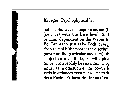

% read the photo
I_text=imread("text1.tif");
figure;
imshow(I_text);
%imtool(I_text);
title("text.tif");

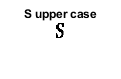

%manually getting the xy cordinats
ys=343;
xs=217;
%end cordinats
deltay=358-ys;
deltax=242-xs;
rectS=[ys xs deltay deltax];
%making the mask
S_Cap_mask=imcrop(I_text,rectS);
imshow(S_Cap_mask);
title("S upper case");

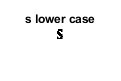

%manually getting the xy cordinats
ys=443;
xs=186;
%end cordinats
deltay=455-ys;
deltax=204-xs;
rects=[ys xs deltay deltax];
s_mask=imcrop(I_text,rects);
imshow(s_mask);
title("s lower case");
%debug


%output with the mask
output1=xcorr2(I_text,S_Cap_mask);
figure;
%use [] to get all the range of values, the default input is a double and the value
%range is 0:1. Therefor we use [].
imshow(output1,[]);

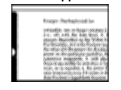

title("Output after S Upper case mask");

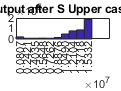

figure;
hist(output1(:));
title("Hist Output after S Upper case mask");

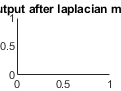

%using laplacian to find the differences in the photo
%laplacian mask
Lap_mask=fspecial("laplacian");

%using negative mask to reverse the values, we want the max value to be
%white color
output_Laplacian=xcorr2(output1,(-Lap_mask));
figure;
imtool(output_Laplacian,[]);
title("Output after laplacian mask");

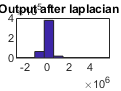

figure;
hist(output_Laplacian(:));
title("Hist Output after laplacian mask");

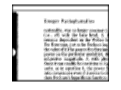

Normal_output_Laplacian=output_Laplacian/max(output_Laplacian,[],"all");
result_Laplacian=sum(Normal_output_Laplacian(:)>0.55);


%find lower case s
%output with the mask
output_s_lower=xcorr2(I_text,s_mask);
figure;
%use [] to get all the range of values, the default input is a double and the value
%range is 0:1. Therefor we use [].
imshow(output_s_lower,[]);
title("Output after s lower case mask");

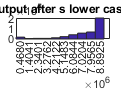

figure;
hist(output_s_lower(:));
title("Hist Output after s lower case mask");

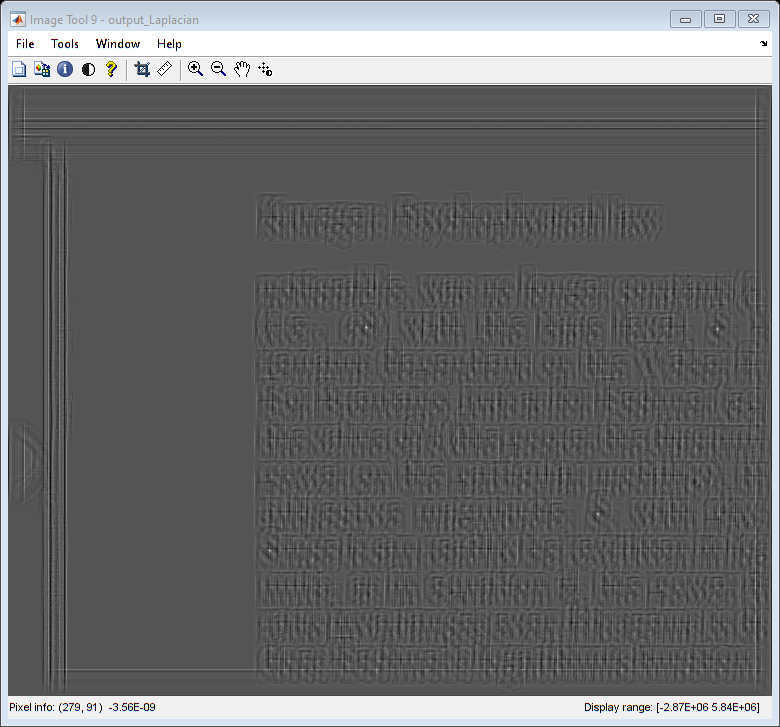

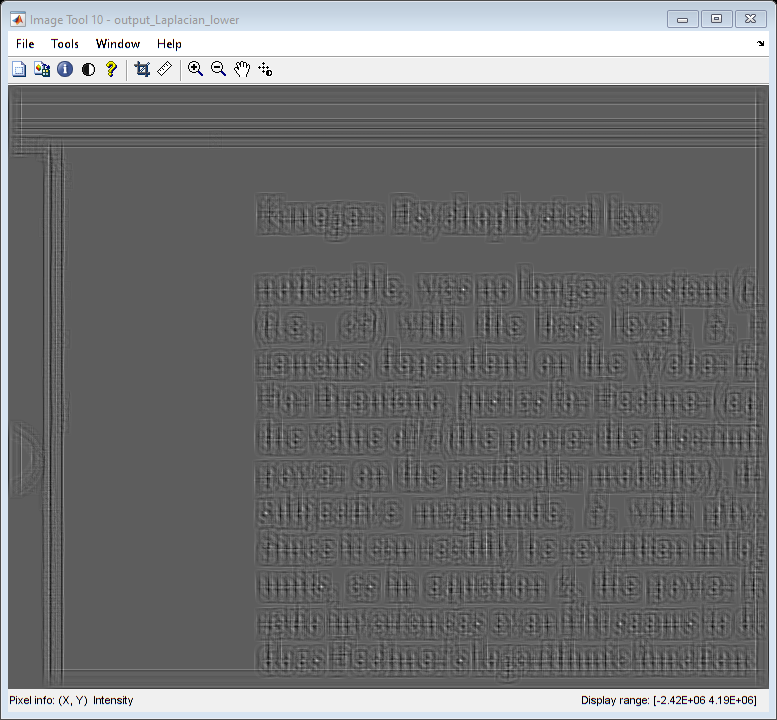


%using negative mask to reverse the values, we want the max value to be
%white color
output_Laplacian_lower=xcorr2(output_s_lower,(-Lap_mask));
figure;
imtool(output_Laplacian_lower,[]);

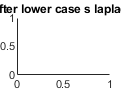

title("Output after lower case s laplacian mask");

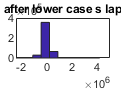

figure;
hist(output_Laplacian_lower(:));
title("Hist Output after lower case s laplacian mask");

Normal_output_Laplacian_lower=output_Laplacian_lower/max(output_Laplacian_lower,[],"all");
result_Laplacian_lower=sum(Normal_output_Laplacian_lower(:)>0.62);

% %for later- use laplacian of gaussian
% log_Mask=fspecial("log");
% output_Log=xcorr2(output,(-log_Mask));
% figure;
% imshow(output_Log,[]);
% title("log");
% figure;
% hist(output_Log(:));
% figure;
% hist(output_Laplacian(:));

## Problem 2

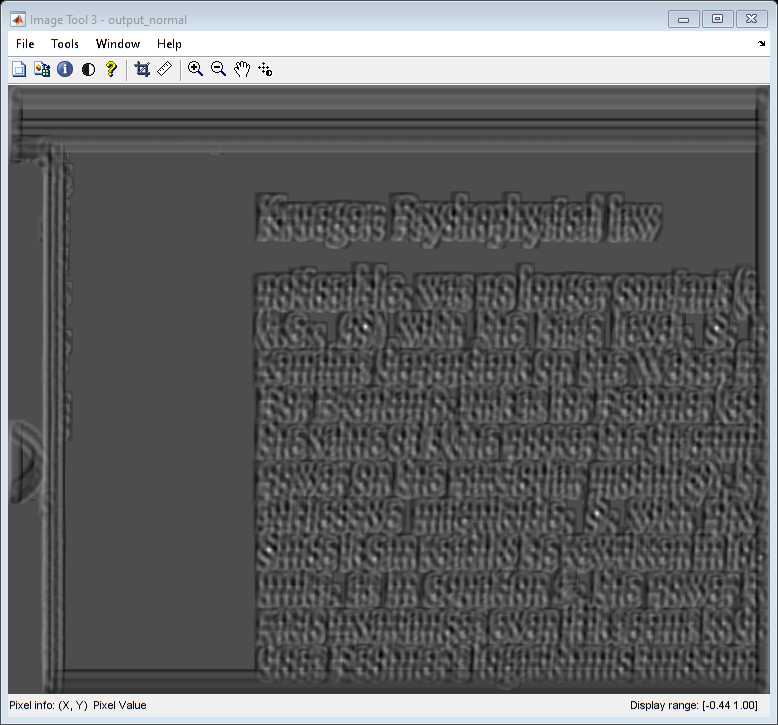

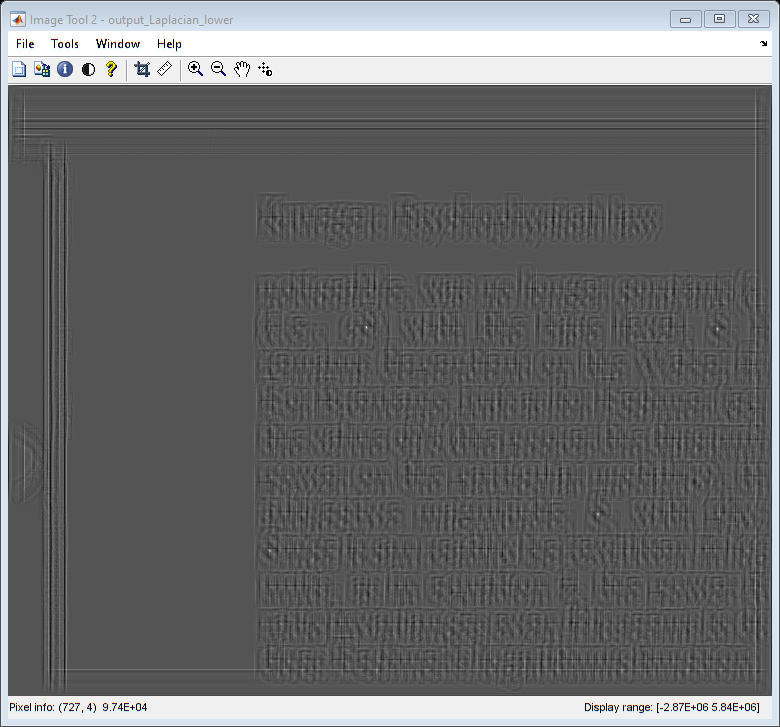

output_normal=normxcorr2(S_Cap_mask,I_text);
figure;
%display
imtool(output_normal,[]); %temp

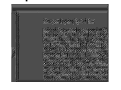

imshow(output_normal,[]);
title("output with normal");

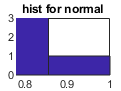

figure;

%count the number of deltas, find all values>0.79 and sum them. We found the
%smallest value using imtool which is 0.79.
result_normal=sum(output_normal(:)>0.79);
hist(output_normal(:));
xlim([0.78,1]);
ylim([0,3]);
title("hist for normal");

%[x,y]=ginput;
%I_text_out=xcorr2(I_text,)

## Problem 3

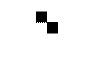

clc,clear,clf;
%create square image
I=zeros(50,50,'uint8');
%making white squares
I(1:25,26:50)=255;
I(26:50,1:25)=255;
%gray pixel at 12,12
I(12,12)=128;
figure;
imshow(I);